# Greybox Modeling (RC)

clc
clear 

# **Data Acquisition**

Reading the data from csv file (OpenStudio results)

filename = 'DataCalibGray_5TZ.xlsx';
MyData = readtable(filename);

% training data consists of the range of data from 1 to 1500
[y ,u ,t_train] = dataSplitter(MyData,1,1500);
[y_test,u_test,t_test] = dataSplitter(MyData,1500,2112);
t_test = t_test*3600;
t_train = t_train*3600;

The data is splitted into two subsets, namely, training data (~70%) and test data (~30%).

odefun = 'RCmodel'

odefun = 'RCmodel'

% function [A,B,C,D] = RCmodel(c1,c2,c3,R1a,R1c,R2c,R2u,R3a,R3u,k1,k3,Ts)
fit_tests_vec = zeros(10,1);
param=[6276.460	1600.033	3527.533	0.000882	0.001364	0.0196	0.001785	0.0011	0.0017];
Ts = 900;
init_sys = idgrey(odefun,param,'cd');


data = iddata(y, u, Ts,'Name', 'RC model');
data.InputName = {'HVAC heater of classroom', 'HVAC heater of auditorium', 'HVAC heater of gym', ...
    'Temperature of ambient','Temperature of corridor', 'Temperature of unconditioned zone', ...
    'Internal gain of classroom', 'Internal gain of auditorium','Internal gain of gym', ...
    'Solar gain of classroom', 'Solar gain of gym'};
data.InputUnit = {'Watt', 'Watt', 'Watt', ...
    '°K','°K', '°K', ...
    'Watt', 'Watt', 'Watt', ...
    'Watt', 'Watt'};
data.OutputName = {'Temperature of classroom','Temperature of auditorium','Temperature of gym'};
data.OutputUnit = {'°K', '°K', '°K'};
data.Tstart = 20;
data.TimeUnit = 's';

sys = greyest(data,init_sys);

testdata = iddata(y_test, u_test, Ts, 'Name', 'RC model');
testdata.InputName = {'HVAC heater of classroom', 'HVAC heater of auditorium', 'HVAC heater of gym', ...
    'Temperature of ambient','Temperature of corridor', 'Temperature of unconditioned zone', ...
    'Internal gain of classroom', 'Internal gain of auditorium','Internal gain of gym', ...
    'Solar gain of classroom', 'Solar gain of gym'};
testdata.InputUnit = {'Watt', 'Watt', 'Watt', ...
    '°K','°K', '°K', ...
    'Watt', 'Watt', 'Watt', ...
    'Watt', 'Watt'};
testdata.OutputName = {'Temperature of classroom','Temperature of auditorium','Temperature of gym'};
testdata.OutputUnit = {'°K', '°K', '°K'};
testdata.Tstart = 20 ;
testdata.TimeUnit = 's';

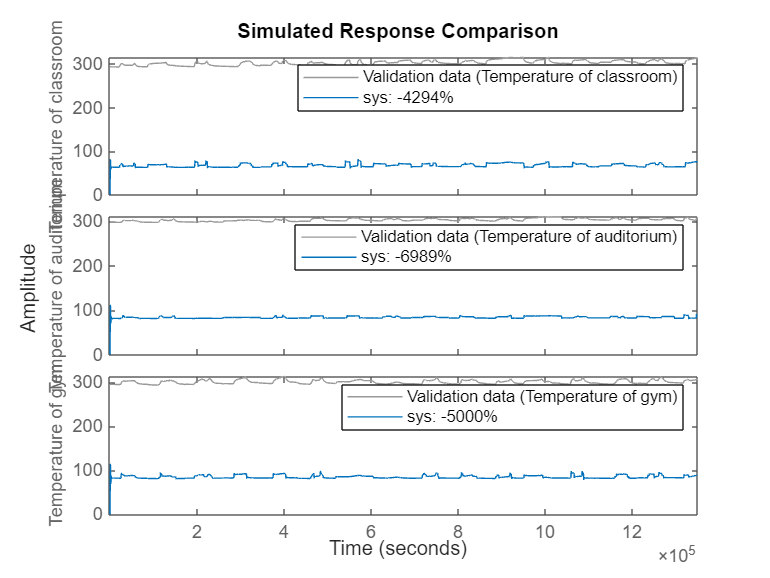

%sys = greyest(testdata,init_sys);
opt = compareOptions('InitialCondition','zero');
compare(data,sys,Inf,opt)

## Fit

[~,fit_test,~] = compare(testdata,sys,Inf,opt);

## System States

A = sys.A

A =    -0.2904         0         0
         0   -0.3808         0
         0         0   -0.4059


A2 = sys.A;
A2(2,2) = A(2,2);
A2(3,3) = A(3,3);
B = sys.B;
sys_mod = ss(A2,sys.B,sys.C,sys.D);

%compare(testdata,sys_mod,Inf,opt);
%display(fit);


%  plot(counter1,fit_test);
%  legend("class","Aud","Gym");
%  xlabel("Parameter");
%  ylabel("NRMS %");
%  grid minor
%  title("Parameter Sensitivity Analysis");
%[R1_grid, R2_grid] = meshgrid(R1, R2);
%surf(counter2,counter1,fit_test);

%  [counter1_grid, counter2_grid] = meshgrid(counter1, counter2);
%  figure;
%  for comp = 1:3
%      subplot(1, 3, comp);
%      surf(counter1_grid, counter2_grid, squeeze(fit_test(comp, :, :)));
%      xlabel('R2c');
%      ylabel('R2u');
%      zlabel(sprintf('Fit Test %d', comp));
%      title(sprintf('Fit Test %d', comp));
%      colormap('jet');
%      colorbar;
% end
% [c1,c2,c3,R1a,R1c,R2c,R2u,R3a,R3u]
y_t = paramFun(sys.B)

y_t = 1.0e+03 *

    6.4644    1.4184    3.6370    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
